Image processing Script for observing whats happening with the data:

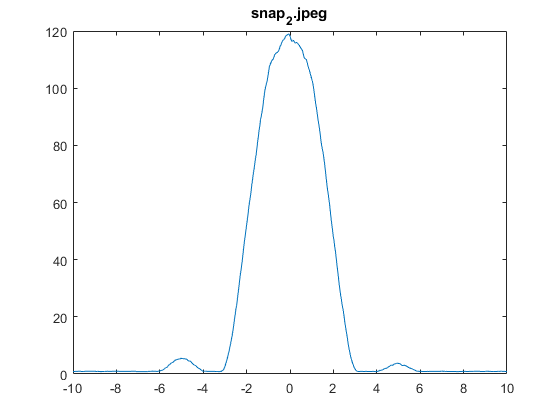

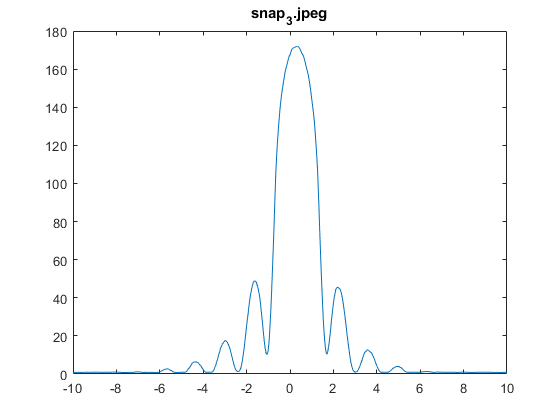

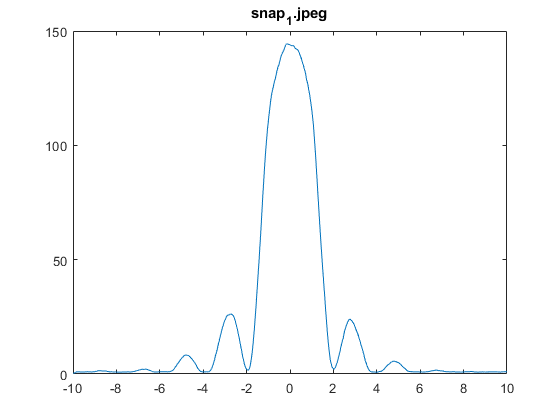

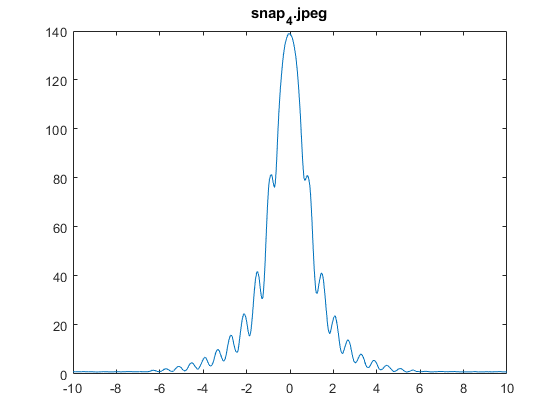

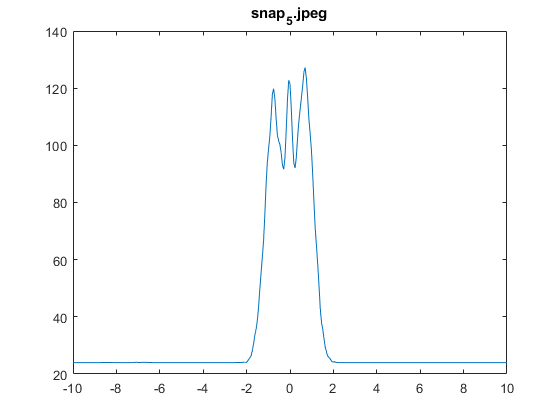

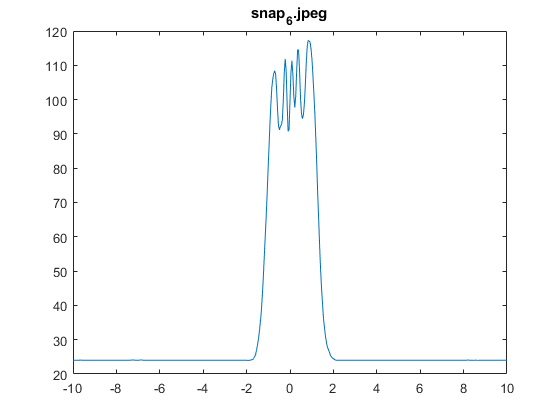

% Importing image from CCD Camera

for i = [2 3 1 4 5 6]
    name=strcat('snap_',num2str(i),'.jpeg');
    
    % Reading Image
    I = imread(name);
    
    % Converting to Greyscale
    I_grey = rgb2gray(I);

    % 3D plot
%     [x,y] = size(I_grey);
%     X = 1:x;
%     Y = 1:y;
%     
%     [xx,yy] = meshgrid(Y,X);
%     i1 = I_grey;
%     i2 = imadjust(i1);
%     
%     figure;mesh(xx,yy,i1);
%     view([0 90])
%     colorbar
%     
%     figure;mesh(xx,yy,i2);
%     view([0 90])
%     colorbar
    
    %Conducting Averages
    intensities = zeros(size(I_grey,2),1);
    j = 1:size(intensities,1);
    intensities(j) = sum(I_grey(:,j)) ./ (size(I_grey,1));
    t = linspace(-10,10,size(intensities,1));
    
    figure;
    plot(t,intensities);
    hold on;
    title(name);
    hold off;
    
end

figure;
imshow(i)